clear; clc; close all; fclose all;

**Generate Pilot Subcarriers:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pilots for M = 2
rng default
pilot_data_m2 = randsrc(4096/4*16,1,0:2-1);
file = fopen('../Xilinx/Sw_Source/ofdm/files/PilotDataM2.txt','wt');
fprintf(file, "%d\n", pilot_data_m2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pilots for M = 4
rng default
pilot_data_m4 = randsrc(4096/4*16,1,0:4-1);
file = fopen('../Xilinx/SW_Source/ofdm/files/PilotDataM4.txt','wt');
fprintf(file, "%d\n", pilot_data_m4);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pilots for M = 16
rng default
pilot_data_m16 = randsrc(4096/4*16,1,0:16-1);
file = fopen('../Xilinx/SW_Source/ofdm/files/PilotDataM16.txt','wt');
fprintf(file, "%d\n", pilot_data_m16);
fclose('all');

**OFDM Parameters:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read OFDM Parameters from TX Frequency file header
file = fopen('../Xilinx/SW_Source/ofdm/files/TxFreqData1.txt','r');
nfft = fscanf(file,"%d,",1);
BW = fscanf(file,"%d,",1);
cp_len = fscanf(file,"%d,",1);
M = fscanf(file,"%d,",1);
ofdm_symbols = fscanf(file,"%d,",1);
tx_scale = fscanf(file,"%d,",1);
freq_data_ofdm = [];
for i = 1:nfft*ofdm_symbols
    tmp_i = fscanf(file,"%d");
    tmp_q = fscanf(file,",%d");
    tmp_iq = complex(tmp_i, tmp_q);
    freq_data_ofdm = [freq_data_ofdm tmp_iq];
end
freq_data_ofdm_1 = reshape(freq_data_ofdm,[nfft ofdm_symbols]);

pilot_density = 0.25; % Hardcoded value

**Calculated OFDM Parameters:**

rep = 1/pilot_density;
pilot_index = 1:rep:nfft;
data_index = 1:nfft;
data_index(pilot_index) = [];
scs = BW/nfft;
num_data_bits = length(data_index)*ofdm_symbols;
pilot_carriers = length(pilot_index);
data_carriers = length(data_index);
n_packed = nfft*M;

% For rest of script
rng default
pilot_data = randsrc(pilot_carriers,ofdm_symbols,0:M-1);

**QAM Modulation:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read TX data bits
file = fopen('../Xilinx/SW_Source/ofdm/files/TxModData1.txt','r');
nfft = fscanf(file,"%d",1);
M = fscanf(file,"%d",1);
ofdm_symbols = fscanf(file,"%d",1);
data_char = fscanf(file,"%d",(data_carriers)*ofdm_symbols);
fclose('all');
data = reshape(data_char,[data_carriers ofdm_symbols]);
mod_data = data;

qpsk_mod_data = qammod(data,M);
reference_pilot = qammod(pilot_data,M);

**Insert Pilots:**

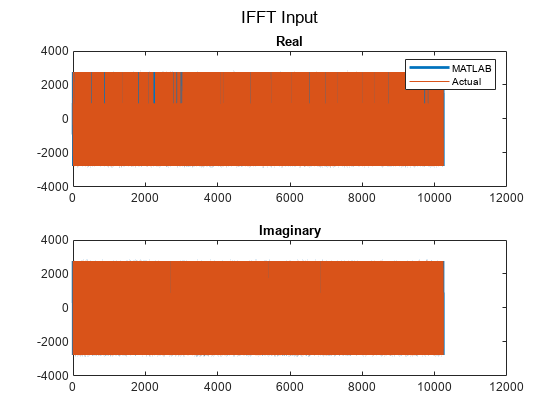

carriers = zeros(nfft,ofdm_symbols);
carriers(pilot_index,:) = reference_pilot;
carriers(data_index,:) = qpsk_mod_data;
carriers = carriers*tx_scale;

carriers_plot = reshape(carriers,[1 ofdm_symbols*nfft]);
figure(),subplot(2,1,1),plot(real(carriers_plot),'LineWidth',2),hold on,plot(real(freq_data_ofdm)),legend('MATLAB','Actual'),title('Real')
subplot(2,1,2),plot(imag(carriers_plot),'LineWidth',2),hold on,plot(imag(freq_data_ofdm)),title('Imaginary'),sgtitle('IFFT Input')

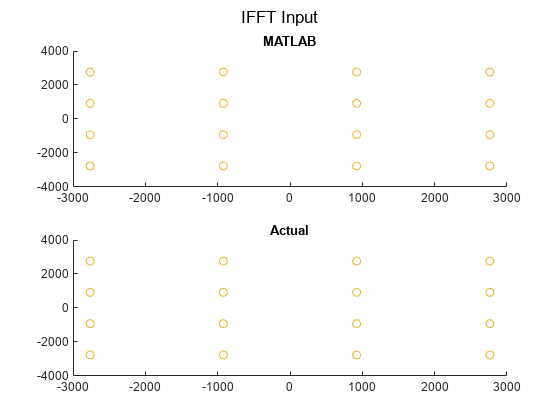

figure(),subplot(2,1,1),scatter(real(carriers),imag(carriers)),title('MATLAB')
subplot(2,1,2),scatter(real(freq_data_ofdm_1),imag(freq_data_ofdm_1)),title('Actual'),sgtitle('IFFT Input')

**Perform IFFT and CP Insertion:**

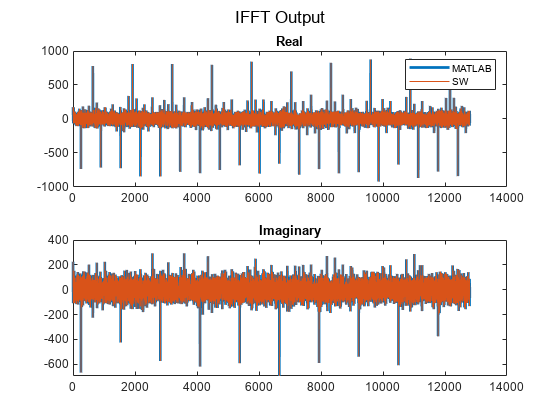

cp_start = nfft-cp_len;
ifft_sub_carriers = ifft(carriers,nfft);
cp = ifft_sub_carriers(cp_start+1:end,:);
ofdm_tx_signal_par = vertcat(cp,ifft_sub_carriers);

file = fopen('../Xilinx/SW_Source/ofdm/files/TxIfftSamples1.txt','r');
nfft_tmp = fscanf(file,"%d,",1);
ofdm_symbols_tmp = fscanf(file,"%d,",1);
cp_len_tmp = fscanf(file,"%d,",1);
if (nfft_tmp~=nfft||ofdm_symbols_tmp~=ofdm_symbols||cp_len_tmp~=cp_len)
    disp('Error with header information')
end
ifft_sw = [];
for i=1:(nfft+cp_len)*ofdm_symbols
    tmp_i = fscanf(file,"%f");
    tmp_q = fscanf(file,",%f");
    tmp_iq = complex(tmp_i, tmp_q);
    ifft_sw = [ifft_sw tmp_iq];
end
fclose('all');

ifft_sub_carriers_re = reshape(ifft_sub_carriers,[1 ofdm_symbols*(nfft)]);
ofdm_tx_signal_re = reshape(ofdm_tx_signal_par,[1 ofdm_symbols*(nfft+cp_len)]);
figure(),subplot(2,1,1),plot(real(ofdm_tx_signal_re),'LineWidth',2),hold on,plot(real(ifft_sw)),legend('MATLAB','SW'),title('Real')
subplot(2,1,2),plot(imag(ofdm_tx_signal_re),'LineWidth',2),hold on,plot(imag(ifft_sw)),title('Imaginary'),sgtitle('IFFT Output')

**Parallel to Serial:**

ofdm_tx_signal_ser = reshape(ofdm_tx_signal_par,[(nfft+cp_len)*ofdm_symbols 1]);

**Channel:**

% AWGN
SNR = 35;
ofdm_tx_signal_ch = awgn(ofdm_tx_signal_ser,SNR,'measured');
% Multipath
multipath = [1 0.1 0.05 0 0 0 0 0];
ofdm_tx_signal_ch = filter(multipath,1,ofdm_tx_signal_ch);

**DDC:**

ofdm_rx_signal_ch = ofdm_tx_signal_ch;

**Serial to Parallel:**

ofdm_rx_signal_par = reshape(ofdm_rx_signal_ch,[nfft+cp_len ofdm_symbols]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Write simulated channel signal to file
file = fopen('../Xilinx/SW_Source/ofdm/files/RxFftInjectData1.txt','wt');
fprintf(file,"%d,\n",nfft);
fprintf(file,"%d,\n",cp_len);
fprintf(file,"%d,\n",ofdm_symbols);
for i = 1:ofdm_symbols*(nfft+cp_len)
    fprintf(file,"%0.6f, %0.6f\n",real(ofdm_rx_signal_ch(i)),imag(ofdm_rx_signal_ch(i)));
end
fclose('all');

**CP Removal:**

cp_rm_signal = ofdm_rx_signal_par;
cp_rm_signal(1:cp_len,:) = [];


**FFT Output:**

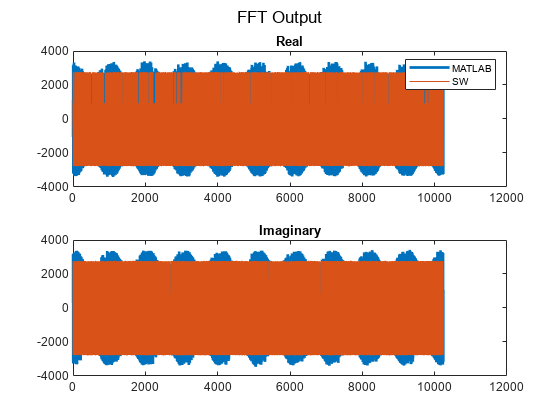

fft_signal = fft(cp_rm_signal);

%file = fopen('../Xilinx/SW_Source/ofdm/files/RxFftSamples1.txt','r');
file = fopen('../Xilinx/SW_Source/ofdm/files/RxFreqData1.txt','r');
nfft_tmp = fscanf(file,"%d,",1);
ofdm_symbols_tmp = fscanf(file,"%d,",1);
cp_len_tmp = fscanf(file,"%d,",1);
if (nfft_tmp~=nfft||ofdm_symbols_tmp~=ofdm_symbols||cp_len_tmp~=cp_len)
    disp('Error with header information');
end
Fft_data_sw = [];
for i = 1:nfft*ofdm_symbols
    tmp_i = fscanf(file,"%lf");
    tmp_q = fscanf(file,",%lf");
    tmp_iq = complex(tmp_i,tmp_q);
    Fft_data_sw = [Fft_data_sw tmp_iq];
end

fft_signal_re = reshape(fft_signal,[1 ofdm_symbols*nfft]);
figure(),subplot(2,1,1),plot(real(fft_signal_re),'LineWidth',2),hold on,plot(real(Fft_data_sw)),legend('MATLAB','SW'),title('Real')
subplot(2,1,2),plot(imag(fft_signal_re),'LineWidth',2),hold on,plot(imag(Fft_data_sw)),title('Imaginary'),sgtitle('FFT Output')

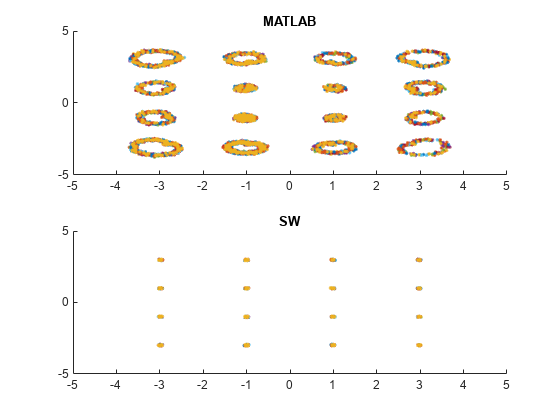

lim = sqrt(M)+1;
y_lim = [-lim lim]; x_lim = [-lim lim];
Fft_data_sw = reshape(Fft_data_sw,[data_carriers+pilot_carriers, ofdm_symbols]);
figure(),subplot(2,1,1),scatter(real(fft_signal/tx_scale),imag(fft_signal/tx_scale),'.'),title('MATLAB'),ylim(y_lim),xlim(x_lim)
subplot(2,1,2),scatter(real(Fft_data_sw/tx_scale),imag(Fft_data_sw/tx_scale),'.'),title('SW'),ylim(y_lim),xlim(x_lim)

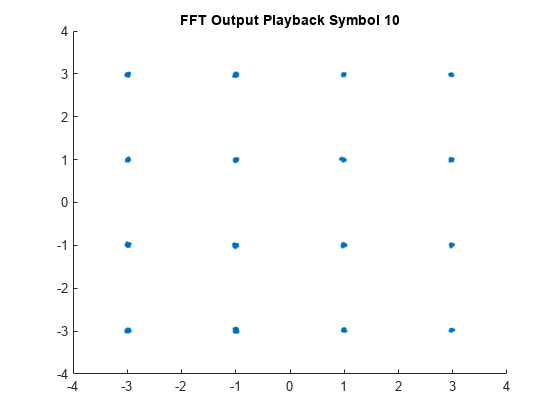

figure()
for i = 1:ofdm_symbols
    scatter(real(Fft_data_sw(:,i)/tx_scale),imag(Fft_data_sw(:,i)/tx_scale),'.')
    title(['FFT Output Playback Symbol ',num2str(i)])
    pause(0.1);
end

**Equalization:**

fft_signal_eq = fft_signal;
fft_signal_eq(pilot_index,:) = [];
Fft_data_sw_eq = Fft_data_sw;
Fft_data_sw_eq(pilot_index,:) = [];


**QAM Demodulation:**

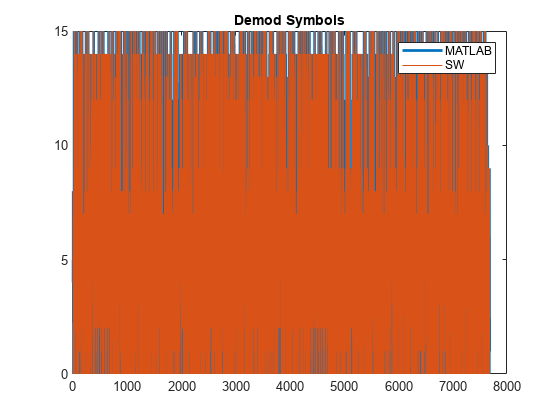

demod_data = qamdemod(fft_signal_eq/tx_scale,M);
demod_sw = qamdemod(Fft_data_sw_eq/tx_scale,M);

demod_data_plot = reshape(demod_data,[1 ofdm_symbols*data_carriers]);
demod_sw_plot = reshape(demod_sw,[1 ofdm_symbols*data_carriers]);
figure(),plot(demod_data_plot,'LineWidth',2),hold on,plot(demod_sw_plot),legend('MATLAB','SW'),title('Demod Symbols')

**Error Rate:**

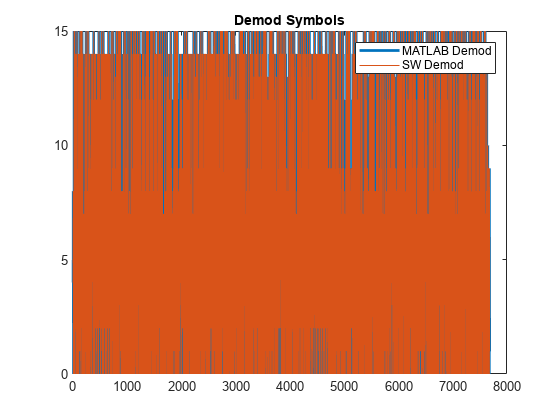


file = fopen('../Xilinx/SW_Source/ofdm/files/RxDemodData1.txt','r');
nfft_tmp = fscanf(file,"%d",1);
M_tmp = fscanf(file,"%d",1);
ofdm_symbols_tmp = fscanf(file,"%d",1);
if (nfft_tmp~=nfft||M_tmp~=M||ofdm_symbols_tmp~=ofdm_symbols)
    disp('Error with header information');
end
data_char_rx = fscanf(file,"%d",(data_carriers)*ofdm_symbols);
fclose('all');

figure(),plot(demod_sw_plot,'LineWidth',2),hold on,plot(data_char_rx),legend('MATLAB Demod','SW Demod'),title('Demod Symbols')


ser_sw = symerr(data_char, data_char_rx)/numel(data_char);
ser_mat = symerr(data, demod_data)/numel(data);

**Analysis:**

evm = comm.EVM(AveragingDimensions=[1 2],MaximumEVMOutputPort=1);
[mat_evm mat_evm_pk] = evm(qpsk_mod_data,fft_signal_eq/tx_scale);
[sw_evm sw_evm_pk] = evm(qpsk_mod_data,Fft_data_sw_eq/tx_scale);

Equalization = ["MATLAB";"SW"];
SER = [ser_mat;ser_sw];
AverageEVM = [mat_evm;sw_evm];
PeakEVM = [mat_evm_pk;sw_evm_pk];
figure(),table(Equalization,SER,AverageEVM,PeakEVM)

ans = 2×4 table
    Equalization    SER    AverageEVM    PeakEVM
    ____________    ___    __________    _______

      "MATLAB"       0       11.296      24.223 
      "SW"           0      0.86793      2.7583 


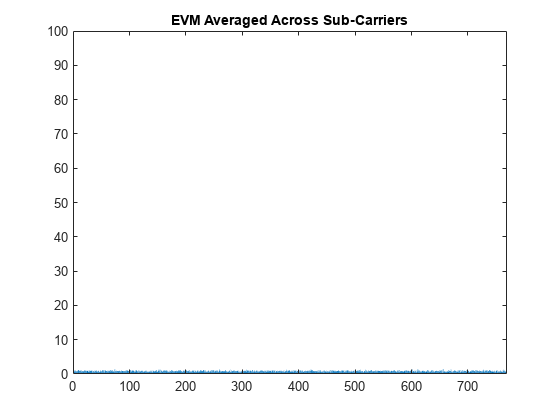

evm = comm.EVM(AveragingDimensions=2);
sw_evm = evm(qpsk_mod_data,Fft_data_sw_eq/tx_scale);
y_lim = [0 100];
y = 1:nfft-pilot_carriers;
figure(),bar(y,sw_evm),title('EVM Averaged Across Sub-Carriers'),ax = gca; ax.YLim = y_lim;

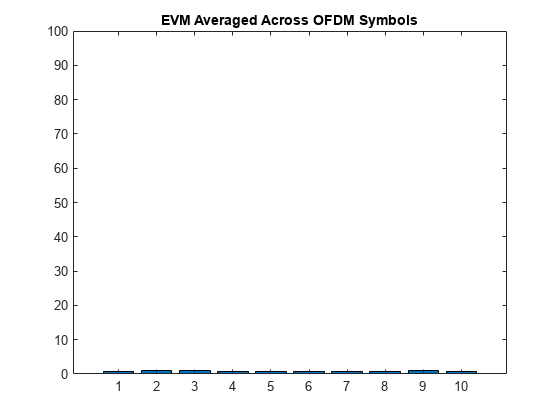

evm = comm.EVM(AveragingDimensions=1);
sw_evm = evm(qpsk_mod_data,Fft_data_sw_eq/tx_scale);
y = 1:ofdm_symbols;
figure(),bar(y,sw_evm),title('EVM Averaged Across OFDM Symbols'),ax = gca; ax.YLim = y_lim;